% clear
% clc
% close all
% 
% % System matrices from system identification model
% A = [-0.0003828 -0.0002208; 0.002247 -0.003235];
% B = [-3.143e-08; -2.666e-05];
% C = eye(2);
% D = 0;
% 
% % Weighting factors
% Q = diag([0.1 10]);
% R = [0.01];
% 
% %Desired equilibrium states for the system.
% xd = [120; 120];
% 
% %Initial conditions
% x0 = [22; 22];
% 
% %LQR solution
% [K, S, E] = lqr(A, B, Q, R);
% 
% 
% %Close loop
% plant = ss(A-B*K, -(A-B*K), C, D);
% 
% %final simulation time 
% tfinal = 15000;
% time_total = 0:0.1:tfinal;
% 
% 
% closed_loop_input = [xd(1)*ones(size(time_total)); xd(2)*ones(size(time_total))];
% 
% [output_closed_loop,time_closed_loop,state_closed_loop] = lsim(plant, closed_loop_input,time_total, x0);
% 
% figure(1);
% plot(time_total,state_closed_loop(:,1))
% xlabel('Time [s]')
% ylabel('Temperature [°C]')
% legend('Temperature of test component')
% grid on;
% 
% figure(2);
% plot(time_total,state_closed_loop(:,2))
% xlabel('Time [s]')
% ylabel('Temperature [°C]')
% legend('Temperature of test component')
% grid on;


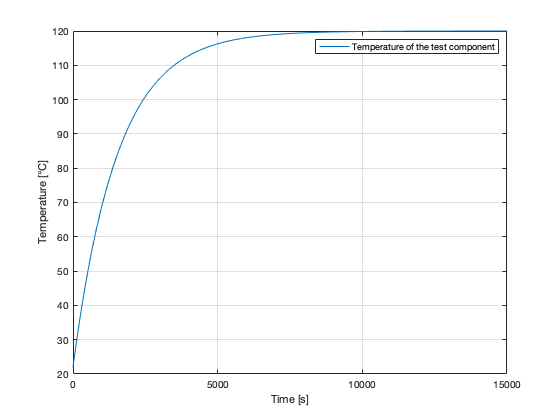

clear
clc
close all

% System matrices from system identification
A = [-0.000636];
B = [4.738e-06];
C = 1;
D = 0;

% Weighting factors
Q = diag([10]);
R = [0.01];

%Desired equilibrium state for the system
xd = [120];

%Initial condition
x0 = [22];

%LQR solution
[K, S, E] = lqr(A, B, Q, R);

%Close loop system
sys = ss(A-B*K, -(A-B*K), C, D);

%Final simulation time 
tfinal = 15000;
time_total = 0:0.1:tfinal;

%Close loop input
closed_loop_input = [xd*ones(size(time_total))];

%Simulation of the temperature response 
[output_closed_loop,time_closed_loop,state_closed_loop] = lsim(sys, closed_loop_input,time_total, x0);

%Plot of the temperature response
figure(1);
plot(time_total, state_closed_loop)
xlabel('Time [s]')
ylabel('Temperature [°C]')
legend('Temperature of the test component')
grid on;